clear


ArfadaCaso1iz=readtable("docTXT\ArfadaCaso1iz.txt");
ArfadaCaso2iz=readtable("docTXT\ArfadaCaso2iz.txt");
ArfadaCaso3iz=readtable("docTXT\ArfadaCaso3iz.txt");
CabeceoCaso1iz=readtable("docTXT\CabeceoCaso1iz.txt");
CabeceoCaso2iz=readtable("docTXT\CabeceoCaso2iz.txt");
CabeceoCaso3iz=readtable("docTXT\CabeceoCaso3iz.txt");
BalanceoCaso1iz=readtable("docTXT\BalanceoCaso1iz.txt");
BalanceoCaso2iz=readtable("docTXT\BalanceoCaso2iz.txt");
BalanceoCaso3iz=readtable("docTXT\BalanceoCaso3iz.txt");

ArfadaCaso1de=readtable("docTXT\ArfadaCaso1de.txt");
ArfadaCaso2de=readtable("docTXT\ArfadaCaso2de.txt");
ArfadaCaso3de=readtable("docTXT\ArfadaCaso3de.txt");
CabeceoCaso1de=readtable("docTXT\CabeceoCaso1de.txt");
CabeceoCaso2de=readtable("docTXT\CabeceoCaso2de.txt");
CabeceoCaso3de=readtable("docTXT\CabeceoCaso3de.txt");
BalanceoCaso1de=readtable("docTXT\BalanceoCaso1de.txt");
BalanceoCaso2de=readtable("docTXT\BalanceoCaso2de.txt");
BalanceoCaso3de=readtable("docTXT\BalanceoCaso3de.txt");
MAA=readtable("docTXT\MAA.txt");
MBB=readtable("docTXT\MBB.txt");
MCC=readtable("docTXT\MCC.txt");


Rotula_Placa=0.051

Rotula_Placa = 0.0510

Placa_Biela=0.0145

Placa_Biela = 0.0145


AlturaPlaca=0.539;
CasoL_m=0.2;
CasoL_b=0.42;
PosXBiela=-0.1;  
PosYBiela=-0.4145;
casoL_ub=Rotula_Placa-Placa_Biela

casoL_ub = 0.0365

PosXEje=0;
PosYEje=-0.4145; 
PosZEje=0.2;

%Casotheta_C=MCC.VCabeceo;
Casotheta_C=-17*pi/180;
Casobeta=MBB.Vbalanceo;
%Casobeta=-6*pi/180;
%Casobeta=0;
Z=0.1;
%CasoZ_arfada=MAA.Var2/1000;
vectorIzquierdo=BalanceoCaso3iz.angulosBalanceo;
vectorDerecho=BalanceoCaso3de.angulosBalanceo;
CasoZ_arfada=Z*ones([1 length(vectorDerecho)]);

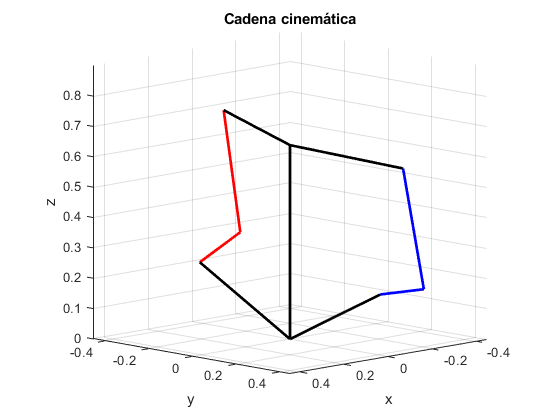


A=[0;0;0]; %Origen
D2=[PosXEje;-PosYEje;PosZEje]; %Punto del eje del motor y>0
vDA2x=linspace(A(1),D2(1),100);
vDA2y=linspace(A(2),D2(2),100);
vDA2z=linspace(A(3),D2(3),100);
D1=[PosXEje;PosYEje;PosZEje]; %Punto del eje del motor y<0
vDA1x=linspace(A(1),D1(1),100);
vDA1y=linspace(A(2),D1(2),100);
vDA1z=linspace(A(3),D1(3),100);

v=VideoWriter('Videos cadena cinemática\B3.avi');
v.Quality=90;
open(v);
figure("Name","Cadena cinemática")
%i=1;
for i=1:length(CasoZ_arfada)  
thetaMiz=vectorIzquierdo(i);
thetaMde=vectorDerecho(i); 
B=[0;0;AlturaPlaca+CasoZ_arfada(i)]; %Origen placa superior
vABx=linspace(A(1),B(1),100);
vABy=linspace(A(2),B(2),100);
vABz=linspace(A(3),B(3),100);
C1=[PosXBiela,PosYBiela,casoL_ub]; %Punto en el plano de union con la biela y<0
Ci1=PosCi(C1,Casotheta_C,Casobeta(i));
Ci1=Ci1(1:3,4);
Ci1=Ci1+B;
vBC1x=linspace(B(1),Ci1(1),100);
vBC1y=linspace(B(2),Ci1(2),100);
vBC1z=linspace(B(3),Ci1(3),100);
C2=[PosXBiela,-PosYBiela,casoL_ub]; %Punto en el plano de union con la biela y>0
Ci2=PosCi(C2,Casotheta_C,Casobeta(i));
Ci2=Ci2(1:3,4);
Ci2=Ci2+B;
vBC2x=linspace(B(1),Ci2(1),100);
vBC2y=linspace(B(2),Ci2(2),100);
vBC2z=linspace(B(3),Ci2(3),100);
Ei1=D1+(CasoL_m.*[cos(thetaMiz); 0; sin(thetaMiz)]);
vDE1x=linspace(D1(1),Ei1(1),100);
vDE1y=linspace(D1(2),Ei1(2),100);
vDE1z=linspace(D1(3),Ei1(3),100);
vEC1x=linspace(Ei1(1),Ci1(1),100);
vEC1y=linspace(Ei1(2),Ci1(2),100);
vEC1z=linspace(Ei1(3),Ci1(3),100);
Ei2=D2+(CasoL_m.*[cos(thetaMde); 0; sin(thetaMde)]);
vDE2x=linspace(D2(1),Ei2(1),100);
vDE2y=linspace(D2(2),Ei2(2),100);
vDE2z=linspace(D2(3),Ei2(3),100);
vEC2x=linspace(Ei2(1),Ci2(1),100);
vEC2y=linspace(Ei2(2),Ci2(2),100);
vEC2z=linspace(Ei2(3),Ci2(3),100);
plot3(vABx,vABy,vABz,'k',"LineWidth",2)
hold on
plot3(vDA1x,vDA1y,vDA1z,'k',"LineWidth",2)
plot3(vBC1x,vBC1y,vBC1z,'k',"LineWidth",2)
plot3(vDE1x,vDE1y,vDE1z,'r',"LineWidth",2)
plot3(vEC1x,vEC1y,vEC1z,'r',"LineWidth",2)
plot3(vDA2x,vDA2y,vDA2z,'k',"LineWidth",2)
plot3(vBC2x,vBC2y,vBC2z,'k',"LineWidth",2)
plot3(vDE2x,vDE2y,vDE2z,'b',"LineWidth",2)
plot3(vEC2x,vEC2y,vEC2z,'b',"LineWidth",2)
hold off
axis("square")
xlim([-0.45 0.45])
ylim([-0.45 0.45])
zlim([0 0.9])
xlabel("x")
ylabel("y")
zlabel("z")
grid on
title("Cadena cinemática")
view([135.124 10.251])
frame=getframe(gcf);
writeVideo(v,frame);
end

close(v);


function [Pf] = PosCi(Pi,theta,beta) 
Pf=[1 0 0 0;0 cos(beta) -sin(beta) 0; 0 sin(beta) cos(beta) 0; 0 0 0 1]*[cos(theta) 0 sin(theta) 0;0 1 0 0; -sin(theta) 0 cos(theta) 0;0 0 0 1]*[1 0 0 Pi(1);0 1 0 Pi(2);0 0 1 Pi(3);0 0 0 1];
end